#                         Procesamiento de señales I (86.51) 

#                    Trabajo Practico I: Diseño de filtros diigitales.

#### Alumno: Brian Alex Fuentes Acuña

#### Padron: 101785

## 1. Introducción 

## 1.1. 

**Objetivo Se requiere procesar una señal de audio transmitida entre dos equipos a través de un determinado medio. En el equipo receptor, la señal se recibe contaminada por varias interferencias de banda angosta, como se observa en la Figura 1.**

      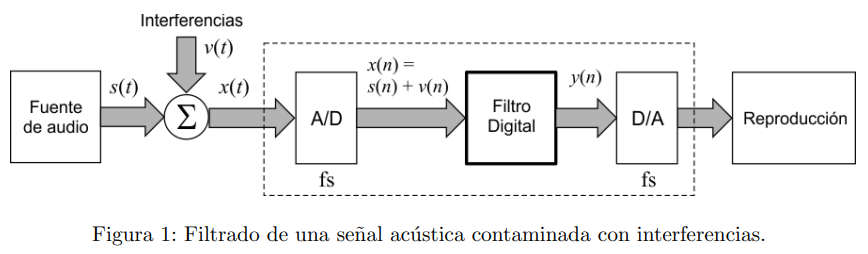

**Para mitigar este problema, afectando lo menos posible a la señal original, se propone el diseño e implementación de un filtro FIR digital de Fase Lineal Generalizada. El diseño deberá contemplar múltiples eliminabandas selectivos en frecuencia.**

## 1.2.

 **Requerimientos La selectividad deberá ser definida de manera tal que el ancho de banda utilizado para suprimir cada componente de interferencia no exceda los 300 Hz. Se requiere que la máxima variación en las bandas de paso y suprimida no superen δp = 0, 08 y δs = 0, 016 respectivamente.**

## 2. Desarrollo

### Problema 1 

**(a) **

**Utilice la función audioread() de Matlab para cargar la señal de interferencias. Grafíque el espectro de dicha señal y verifique las frecuencias de las tres componentes principales.**

clear; close all; clc
addpath("C:\Users\brian\OneDrive\Escritorio\PrcSeñales1\FiltrosDigitales\TP1_FiltrosDigitales\CANCIONES");

%Señales
[S1, Fs_1] = audioread("Pista_01.wav");
[S2, Fs_2] = audioread("Pista_02.wav");
[S3, Fs_3] = audioread("Pista_03.wav");
[S4, Fs_4] = audioread("Pista_04.wav");
[S5, Fs_5] = audioread("Pista_05.wav");
%interferencias
[V1, Fs_v1] = audioread("interferencias.wav");
%[V2, Fs_v2] = audioread("interferencias2.wav");
f1 = 1400; % Hz
f2 = 2735; % Hz
f3 = 3772; % Hz

Para definir los puntos se toma la longitud de puntos del ruido, pero estas son demasiadas y MATLAB (al menos en LiveScript) tiende a recortar los tamaños para reducir tiempo, así que se lo achica pero aun así es indistinto.

Se procede a graficar el espectro del ruido en escala logarítmica para confirmas las frecuencias dadas.

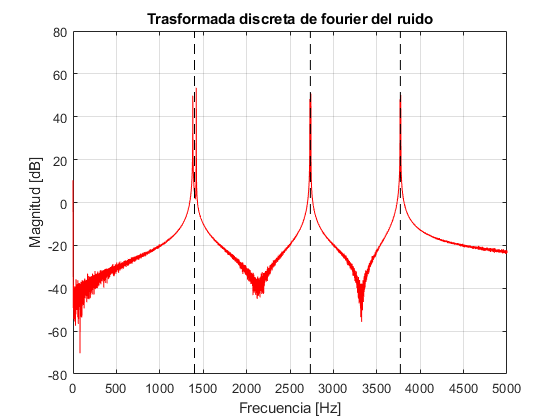

NFFT= length(V1)/10;
% Ejes de frecuencia.
F = ( (0 : 1/NFFT : 1-1/NFFT) * Fs_v1).';
w = linspace(0, 2*pi, NFFT);

figure(1)
    FFTN = fft(V1, NFFT);  %Transformada de fourier
    plot( F(1:NFFT/2), 20*log10( abs( FFTN(1:NFFT/2) ) ), 'r');
    xlabel("Frecuencia [Hz]")
    ylabel("Magnitud [dB]")
    xlim([0 5000])
    title("Trasformada discreta de fourier del ruido")
    %f1 = 1400 Hz, f2 = 2735Hz y f3 = 3772 Hz
    
    hold on
    plot([1400, 1400], [-80,80],'--k')
    plot([2735, 2735], [-80,80],'--k')
    plot([3772, 3772], [-80,80],'--k')
    grid on

A su vez se grafica el espectro de una señal de entrada, para así comprarla con la del ruido y comprender por qué se debe filtrar.

Notar que el espectro de la señal va de $0$ a $22 Khz$, claramente el ruido queda dentro del ancho de banda de las señales por lo que es necesario eliminarlas sin modificar demasiado la señal original.

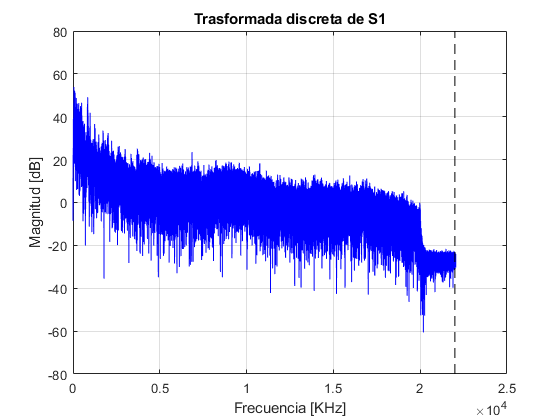

figure(2)
    FFT1 = fft(S1, NFFT);  %Transformada de fourier
    
    plot( F(1:NFFT/2), 20*log10( abs( FFT1(1:NFFT/2) ) ), 'b');
    xlabel("Frecuencia [KHz]")
    ylabel("Magnitud [dB]")
    %xlim([0 5000])
    title("Trasformada discreta de S1")
    %f1 = 1400 Hz, f2 = 2735Hz y f3 = 3772 Hz
    %ANCHO DE VANDA SEÑAL 2.2KHz.
    hold on
    plot([22000, 22000], [-80,80],'--k')
    grid on

**(b) **

**Defina las especificaciones del filtro para eliminar las interferencias de banda  angosta en base a los criterios establecidos. Haga un esquema indicando: frecuencias de paso ωp y supresión ωs; ancho de transición del filtro ∆ω; ripple en las bandas de paso y supresión δp y δs. Justifique qué tipo FLG sería adecuado para este diseño.**

Para eliminar las interferencias se deben crear elimina bandas, 3 notch, los cuales deben de ser diseñados teniendo en cuenta las características generales y las componentes en frecuencias del ruido.

Para ello se hace uso del siguiente modelo de un Nocht. 

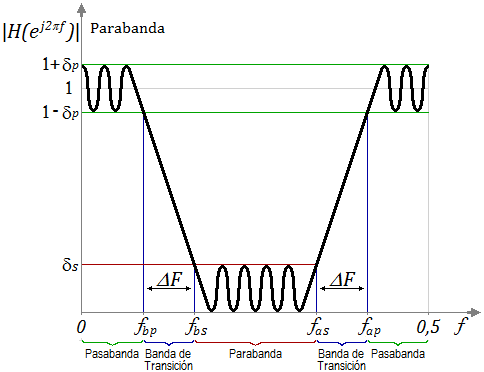

De donde se sabe que $\Delta F_{TOT_{MAX}}=f_{ap}-f_{bp}$ = $300 Hz$ y $\delta_{P_{MAX}} = 0.08$ $\delta_{S_{MAX}}= 0.016$.

Como primera aproximación se podría $\Delta F$=$\Delta F_{MAX}$  y de ser necesario se reducirá el ancho de banda, pero en las componentes de ruido no está exactamente en las frecuencias $f_1$, $f_2$ y $f_3$ sino en sus alrededores por lo que se debe definir el ancho de banda de supresión, $\Delta Bs_f = f_{as} - f_{bs}$ y para ello hay que tener en cuenta que en $f_1$ la hay dos picos de frecuencia en $1380 Hz$ y $1420 Hz$ y como estas frecuencias son las de mayor distancia respectiva a $f_2$ y $f_3$ se define un ancho de banda de supresión minimo

$\Delta Bs_{f _{min}}= 1420 Hz- 1380Hz = 40Hz$.

En la siguiente imagen se muestra un acercamiento a $f_1$ en donde se ve que en realidad hay dos picos de frecuencia alrededor de $f_1$.

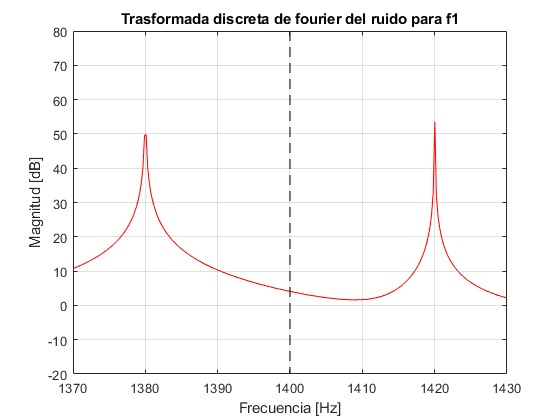

figure(3)
    FFTN = fft(V1, NFFT);  %Transformada de fourier
    
    plot( F(1:NFFT/2), 20*log10( abs( FFTN(1:NFFT/2) ) ), 'r');
    xlabel("Frecuencia [Hz]")
    ylabel("Magnitud [dB]")
    xlim([f1-30 f1+30])
    ylim([-20 80])
    title("Trasformada discreta de fourier del ruido para f1")
    %f1 = 1400 Hz, f2 = 2735Hz y f3 = 3772 Hz   
    hold on
    plot([1400, 1400], [-80,80],'--k')

    grid on

y además como se quiere un Nocht las frecuencias de interés no son ni altas ni bajas por lo que será de $Tipo I$ según: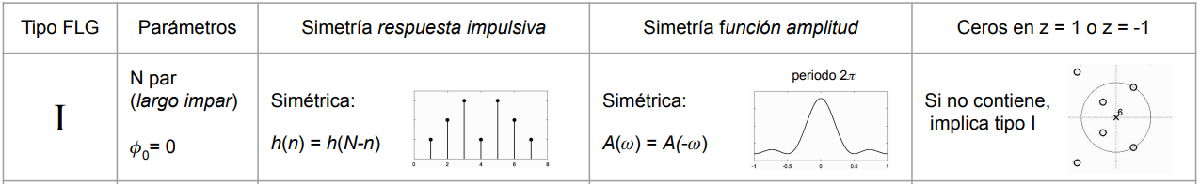

Asi entonces el filtro debe ser con $M: impar$ y $simetrico$.

### **Problema 2 **

**(a) **

**Implemente el filtro FIR para eliminar las interferencias mediante el método equirriple. Para obtener la respuesta impulsiva del filtro (no se requiere implementar el algoritmo), puede usar la función firpm() de Maltab. De acuerdo al gráfico de especificaciones del Problema 1, defina los vectores de entrada de la función de Matlab (frecuencias, amplitudes y pesos). Utilice la aproximación de Kaiser [1] (Ec. 10.2.94) para computar el orden del filtro (tenga en cuenta puede llegar a ser necesario modificarlo iterativamente hasta lograr el mejor cumplimiento de las especificaciones).**

Para ello se definen los parámetros pedidos y se elige un ancho de banda de transición y un ancho de banda de rechazo 

estas especificaciones no exceden los requerimientos y fueron obtenidas a simple vista de los gráficos anteriores y en las pruebas finales lograron un buen resultado cualitativo.

%Parametros para Kaiser

x=sym('x','real');
%Requerimientos.
deltaP = 0.080;
deltaS = 0.016;
Fs= Fs_1;  %todas las frecuencias de muestreo son iguales
D2f_M = 300; %Hz maximo ancho de banda.

Df= 100; %Hz
DBfs= 50; %Hz
% Df + DBf + Df = 250 < 300

%-En frecuencia angular es:
Dw = 2*pi*Df/Fs;
DBWs = 2*pi*DBfs/Fs; 

w1= 2*pi*f1/Fs;
w2= 2*pi*f2/Fs;
w3= 2*pi*f3/Fs;

%Obtengo la aproximacion de Kaiser para calcular el orden.
%NADA TIENE QUE VER CON LA VENTANA DE KAISER.
M_= @(delta1, delta2, Dw)( (-20*log10( sqrt(delta1*delta2) ) - 13) / (14.6*Dw) + 1 );
M = ceil( M_(deltaP, deltaS, Dw));
N= M - 1

N = 77

Usando la estimación del orden con la aproximación de Kaiser se obtiene $M= 78$ pero se sabe que tiene que ser impar para ser tipo I y además este orden no cumple con el ripple pedido lo cual es esperable, después de todo es una primera aproximación, lo que si no fue esperable es que esta aproximación haya estado demasiado alejada del orden aceptable $M = 603$.

%Ajuto el orden
N = N + 525 %(N : PAR, M= IMPAR )

N = 602

Luego hay que definir las bandas de frecuencias para usar el equiripple, para ello hay que definir 4 frecuencias para cada frecuencia dada.

es decir, cuatro frecuencias para cada notch. $W_{bp}$ $W_{bp}$ $W_{ap}$y $W_{as}$ según la definición mostrada.

%Bandas de frecuencia
%Dw = 100 DBw= 50;
wbp1 = w1 - DBWs/2 - Dw;
wbs1 = w1 - DBWs/2;
wap1 = w1 + DBWs/2;
was1 = w1 + DBWs/2 + Dw;

wbp2 = w2 - DBWs/2 - Dw;
wbs2 = w2 - DBWs/2;
wap2 = w2 + DBWs/2;
was2 = w2 + DBWs/2 + Dw;

wbp3 = w3 - DBWs/2 - Dw;
wbs3 = w3 - DBWs/2;
wap3 = w3 + DBWs/2;
was3 = w3 + DBWs/2 + Dw;

vp = 1/(deltaP);  
vs = 1/(deltaS);
%las frecuencias deben ir entre 0 y 1(para w, debe estar normalizado a pi).
F_ = [0 wbp1 wbs1 wap1 was1 wbp2 wbs2 wap2 was2 wbp3 wbs3 wap3 was3 pi]./pi;
A_ = [1   1   0   0     1    1    0    0    1    1    0    0    1   1 ];
V_ = [ vp      vs         vp        vs        vp        vs        vp ];

%Filtro Equiripple.
EquiRP = firpm(N, F_, A_, V_);

**(b) **

**Grafique la respuesta impulsiva del filtro h[n], el módulo de su respuesta en frecuencia   |H(ω)| (respuesta completa en el intervalo [0, π) y un acercamiento en cada banda eliminada), diagrama de polos y ceros y retardo de grupo. Verifique si el diseño se ajusta apropiadamente a las especificaciones de frecuencia y ripples. De acuerdo al filtro obtenido, ¿Cuál es el tipo FLG resultante?**

n= 0:N;
% fft del Equiripple diseñado
fftEqRP= fft(EquiRP, NFFT);

Se puede observar como la respuesta impulsiva es simétrica tal como se esperaba siendo de $tipo I$

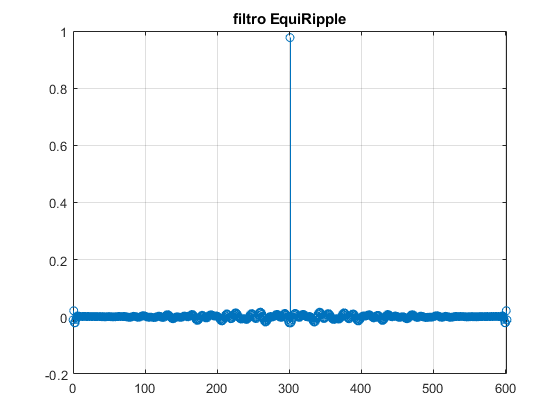

%grafico h(n) respuesta impulsiva.
figure()
stem(n,EquiRP)
xlim([0 N])
grid on
title("filtro EquiRipple")

Luego el modulo de la respuesta en frencuencia de $0$ a $\pi$ es

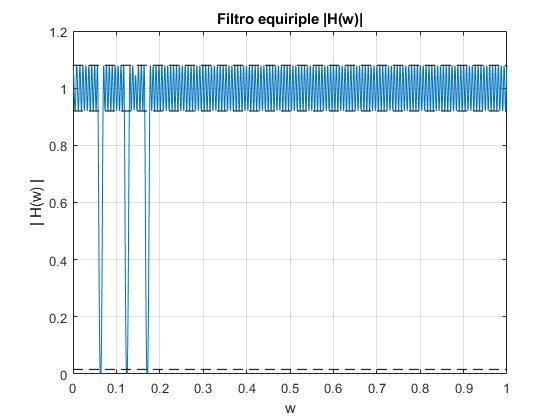

%grafico |H(w)|, modulo respuesta en frecuencia.
figure()
    plot(w/pi, abs(fftEqRP))
    title("Filtro equiriple |H(w)|")
    xlabel("w")
    ylabel("| H(w) |")
    hold on;
    plot([0, 1],[1+ deltaP, 1+ deltaP], '--k')
    plot([0, 1],[1- deltaP, 1- deltaP], '--k')
    
    plot([0, 1],[deltaS,  deltaS], '--k')
    grid on;
    xlim([0, 1])    

Notar en el siguiente acercamiento que se cumple lo pedido, donde los $\delta_P$ y $\delta_S$ están dentro de los limites pedidos.

y en rojo se marca $\Delta F$ traducido a las frecuencias angulares alrededor de $f_1$ y se observa que es mayor al ancho de banda obtenido.

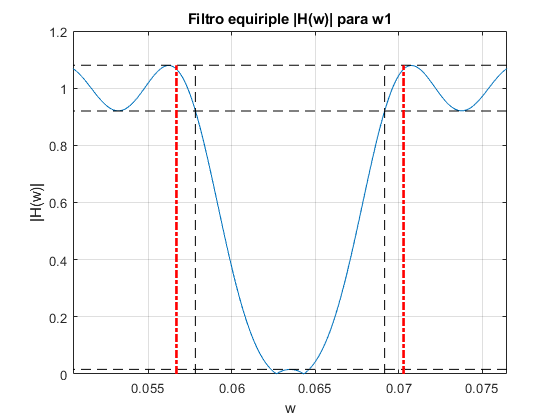

% acercamiento para f1
figure()
    plot(w/pi, abs(fftEqRP))
    title("Filtro equiriple |H(w)| para w1")
    hold on;
    plot([0, 1],[1+ deltaP, 1+ deltaP], '--k')
    plot([0, 1],[1- deltaP, 1- deltaP], '--k')
    
    plot([0, 1],[deltaS,  deltaS], '--k')
    
    plot([wbp1, wbp1]/pi, [0, 1+deltaP],'--k')
    plot([was1, was1]/pi, [0, 1+deltaP],'--k')
    DW_MAX = 2*pi*(D2f_M/2)/Fs;
    plot([w1 + DW_MAX, w1 + DW_MAX]/pi, [0, 1+deltaP],'-.r', "LineWidth",2)
    plot([w1 - DW_MAX, w1 - DW_MAX]/pi, [0, 1+deltaP],'-.r', "LineWidth",2)
    grid on;
    xlabel("w"); ylabel("|H(w)|")
    xlim([w1 - 0.013*pi, w1 + 0.013*pi]/pi)     

Luego se verifica para $f_2$ y $f_3$ respectivamente.

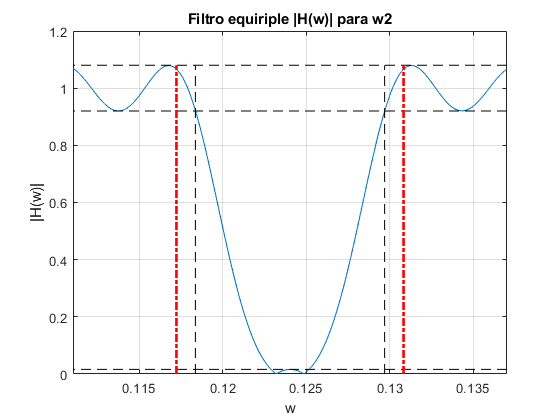

%Acercamiento para f2:
figure()
    plot(w/pi, abs(fftEqRP))
    title("Filtro equiriple |H(w)| para w2")
    hold on;
    plot([0, 1],[1+ deltaP, 1+ deltaP], '--k')
    plot([0, 1],[1- deltaP, 1- deltaP], '--k')
    
    plot([0, 1],[deltaS,  deltaS], '--k')
    
    plot([wbp2, wbp2]/pi, [0, 1+deltaP],'--k')
    plot([was2, was2]/pi, [0, 1+deltaP],'--k')
    DW_MAX = 2*pi*(D2f_M/2)/Fs;
    plot([w2 + DW_MAX, w2 + DW_MAX]/pi, [0, 1+deltaP],'-.r', "LineWidth",2)
    plot([w2 - DW_MAX, w2 - DW_MAX]/pi, [0, 1+deltaP],'-.r', "LineWidth",2)
    grid on;
    xlabel("w"); ylabel("|H(w)|")
    xlim([w2 - 0.013*pi, w2 + 0.013*pi]/pi)

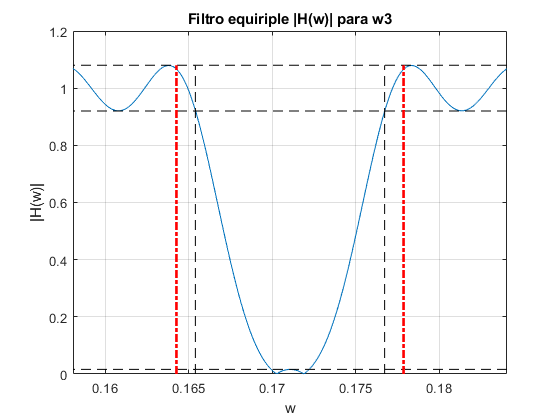

%Acercamiento para f3:
figure()
    plot(w/pi, abs(fftEqRP))
    title("Filtro equiriple |H(w)| para w3")
    hold on;
    plot([0, 1],[1+ deltaP, 1+ deltaP], '--k')
    plot([0, 1],[1- deltaP, 1- deltaP], '--k')
    
    plot([0, 1],[deltaS,  deltaS], '--k')
    
    plot([wbp3, wbp3]/pi, [0, 1+deltaP],'--k')
    plot([was3, was3]/pi, [0, 1+deltaP],'--k')
    DW_MAX = 2*pi*(D2f_M/2)/Fs;
    plot([w3 + DW_MAX, w3 + DW_MAX]/pi, [0, 1+deltaP],'-.r', "LineWidth",2)
    plot([w3 - DW_MAX, w3 - DW_MAX]/pi, [0, 1+deltaP],'-.r', "LineWidth",2)
    grid on;
    xlabel("w"); ylabel("|H(w)|")
    xlim([w3 - 0.013*pi, w3 + 0.013*pi]/pi)

Se confirma que se cumple con lo pedido.

Entonces se procede a graficar el diagrama de polos y ceros y efectivamente se puede comprobar que es un $tipo I$ puesto que no hay ceros en $z=-1$ o $z=1$(en LiveScript) se puede realizar un acercamiento.

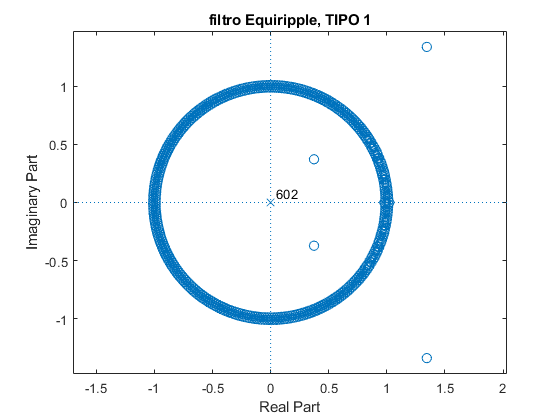

%Diagrama de polos y ceros.
figure()
    zplane(EquiRP, 1)
    title("filtro Equiripple, TIPO 1")

Finalmente, el retardo de grupo es de constante e igual a $301$, esto aumenta a medida que aumenta el orden del filtro aunque en este TP no afecta debe ser considerado en otras aplicaciones.

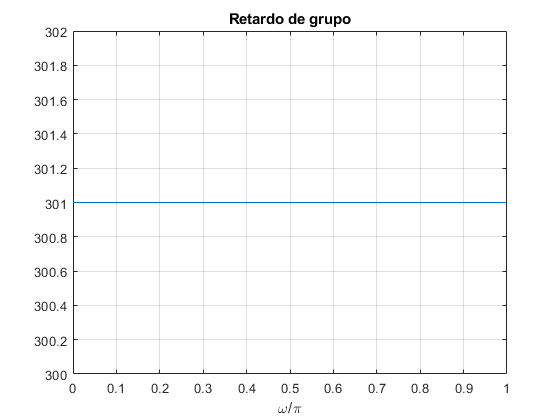

%Retardo de grupo.
figure()
    [gd, w] = grpdelay(EquiRP,length(w));
    plot(w/pi, gd)
    grid on
    xlabel('\omega/\pi')
    title('Retardo de grupo')

**(c) **

**Grafique la función amplitud A(ω) (utilizando la función zerophase()) y determine experimentalmente la cantidad de alternancias. Puede utilizar *****islocalmin()***** e *****islocalmax()***** para calcular mínimos y máximos locales (tenga en cuenta que en ω = 0 y ω = π pueden no ser contemplados por estas funciones y deben verificarse). De acuerdo a lo observado, verifique si se cumple el teorema de alternancias.**

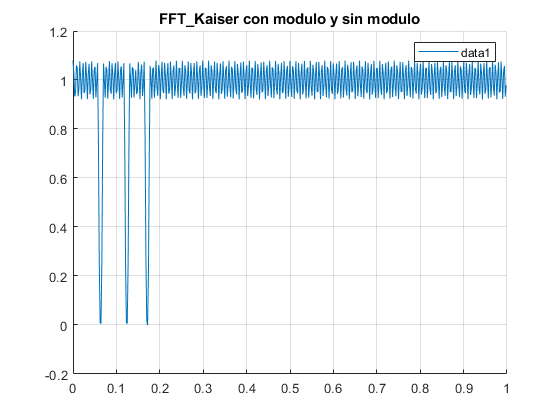

%%Tiene en cuenta la fase que absorve el modulo, los saltos de pi
[A, w, phi] = zerophase(EquiRP, 1, w);
%[A, w, phi] = zerophase(EquiRP, 1, w);
    
figure()
    hold on
    plot(w/pi, A), title('FFT\_Kaiser con modulo y sin modulo')
    xlim([0 1])
    legend()
    grid on;
    hold off

Se grafica la función amplitud y a simple vista puede verse que faltan muestras, esto es propio del LiveScript, quita muestras para acelerar la ejecución del Código.

pero aun así es suficiente para entender lo que se ve y poder contar las alternancias.

Los cuáles serán la suma de los máximos y mínimos encontrados por las funciones $islocalmin$ e $islocalmax$ a los cuales se les debe de sumar #2 por que las funciones no cuentan la de los extremos más otros #12 debido a las 4 frecuencias que suma cada notch.

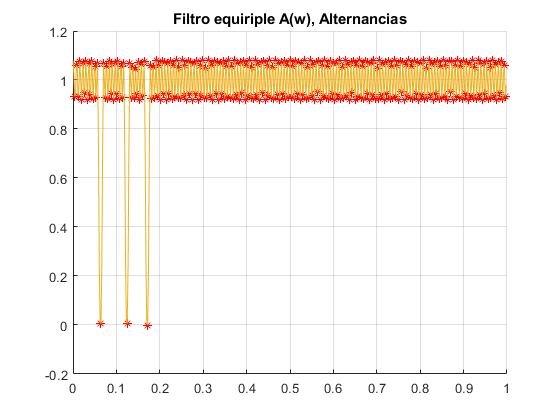

figure()
    [A, w, phi]= zerophase(EquiRP, 1, w);
    [TF_m,P_m]= islocalmin(A);
    [TF_M,P_M]= islocalmax(A);
    hold on
    plot(w(TF_m)/pi, A(TF_m), 'r*')
    plot(w(TF_M)/pi, A(TF_M), 'r*')
    
    plot(w/pi, A)
    title("Filtro equiriple A(w), Alternancias")
    xlim([0 1])
    grid on

    
    %%Para calcular las alternancias hay que tener en cuenta que las
    %%funciones islocalmin e islocalmax no cuentan los extremos, es por
    %%ello que hay que sumarlos visualmente.
    %r ~ (#min + #max) + (3 x #w de paso en deltas) + 2(extremos)
    r = (length(P_m(TF_m)) + length(P_m(TF_m))) +  12 + 2

r = 306

    L = (N)/2    

L = 301

Como es un tipo I se debe usar $L = \frac{M-1}{2}$ entonces se tiene $r=306$ y $L=301$ luego se cumple $r > L+2$ el teorema de alternancias.

**(d)**

** Para algunas de las señales de audio suministradas s[n], genere la versión contaminada con interferencias x[n] = s[n] + v[n] y luego aplique el filtro implementado. Grafique el espectrograma de la señal contaminada x[n] y filtrada y[n].**

cada señal de audio como el ruido tienen tiempos diferentes es decir longitudes diferentes por lo que sumar el ruido no es directo.

se decide cortar la señal de ruido a la longitud de la señal que se le quiera sumar.

%en cualquier caso Si, i={1..5} tiene menor cantidad de muestras que el
%ruido, entonces solo sumo ruido muestra a muestra cortando V1.
x1 = S1 +  V1(1:length(S1));
x2 = S2 +  V1(1:length(S2));
x3 = S3 +  V1(1:length(S3));
x4 = S4 +  V1(1:length(S4));
x5 = S5 +  V1(1:length(S5));


%Para la primer señal.
NFFT = length(x1)/100

NFFT = 7.2799e+03

Luego se obtienen el espectro de la seña con ruido para luego aplicarle el filtro diseñado mediante la convolución en tiempo discreto. 

h = firpm(N, F_, A_, V_);

%FFT señal con ruido
S1F = fft(S1, NFFT);

X1 = fft(x1, NFFT);

%FFT señal filtrada con equiripple
y1 = conv(h, x1);
Y1 = fft(y1, NFFT);

Observar las diferencias que hay entre la señal original(azul) y la señal con ruido(rojo) , se alcanza a ver como con ruido sumado aumenta la amplitud de la señal original en general y no solo donde se encuentran las frecuencias de interés (f1 f2 y f3) esto quiere decir que aunque eliminásemos solo las frecuencias de interés, la señal filtrada nunca volverá a ser exactamente como la original, aunque estas diferencias que apenas se notan en escala logarítmica son imperceptibles al menos para alguien sin oído entrenado.

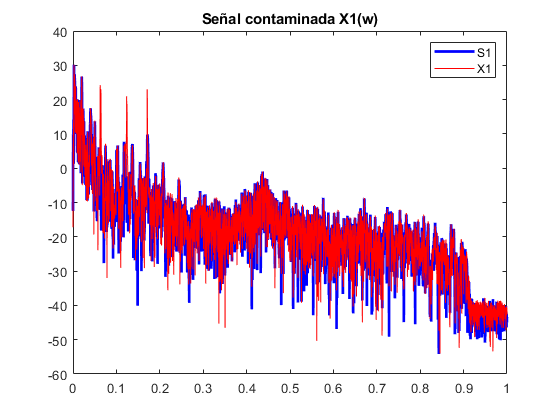

w = linspace(0, 2*pi, NFFT)';

%-Señal contaminada:
%f = w./(2*pi*Ts);
figure()
    plot(w/pi, 20*log10(abs(S1F)),'-b', "LineWidth", 2);
    hold on
    plot(w/pi, 20*log10(abs(X1)), '-r')
    xlim([0 1])
    legend("S1", "X1")
    title("Señal contaminada X1(w)")

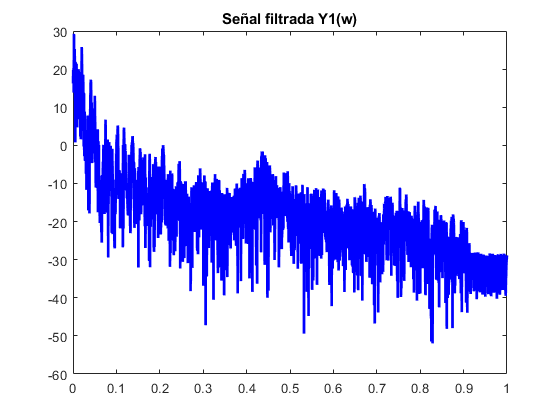

    
%%Señal filtrada:
figure()
    plot(w/pi, 20*log10(abs(Y1)), 'b', "LineWidth", 2)
    xlim([0 1])
    title("Señal filtrada Y1(w)")    

%Para la segunda señal
NFFT = length(x2)/100

NFFT = 1.7510e+04


%FFT señal con ruido
S2F = fft(S2, NFFT);

X2 = fft(x2, NFFT);

%FFT señal filtrada con equiripple
y2 = conv(h, x2);
Y2 = fft(y2, NFFT);

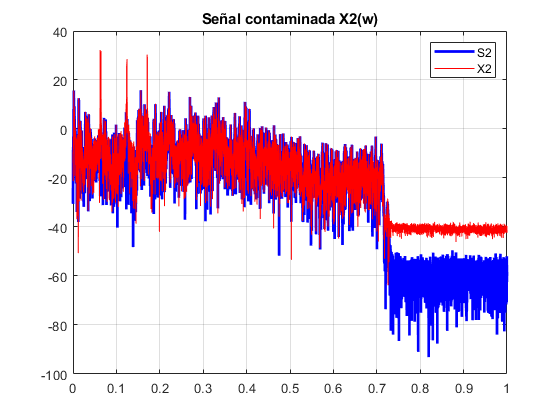



w = linspace(0, 2*pi, NFFT)';
%F = ( (0 : 1/NFFT : 1-1/NFFT) * Fs).';

%-Señal contaminada:
%f = w./(2*pi*Ts);
figure()
    plot(w/pi, 20*log10(abs(S2F)),'-b', "LineWidth", 2);
    hold on
    plot(w/pi, 20*log10(abs(X2)), '-r')
    xlim([0 1])
    grid on
    legend("S2", "X2")
    title("Señal contaminada X2(w)")

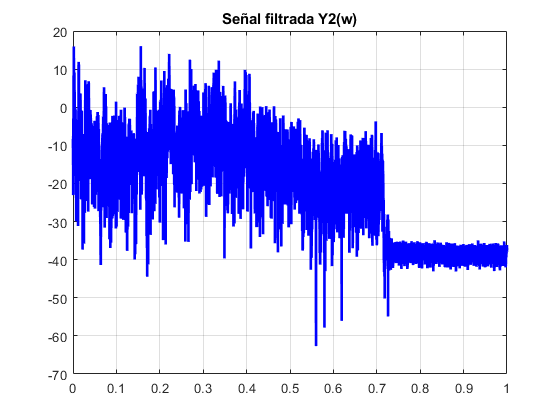

    
%%Señal filtrada:
figure()
    plot(w/pi, 20*log10(abs(Y2)), 'b', "LineWidth", 2)
    xlim([0 1])
    grid on
    title("Señal filtrada Y2(w)")

En la última imagen se puede ver mejor como ha aumentado la amplitud a altas frecuencias acentuando más lo comentado anteriormente.

**(e)**

** Haga un análisis de forma subjetiva, utilizando la función sound(pista, fs), y evalúe si ha logrado cancelar las interferencias sin afectar sustancialmente la calidad de la señal original. Reproduzca las señales en el siguiente orden: **

**1_ Señal con interferencias x[n].**

**2_ Señal filtrada y[n]. **

**3_ Señal original s[n].**

%Señal con interferencias
disp("Señal con interferencias");

Señal con interferencias


sound(x1, Fs)
pause(length(S1)/Fs)


%Señal filtrada
disp("Señal filtrada");

Señal filtrada


sound(y1, Fs)
pause(length(S1)/Fs)


%Señal original
disp("Señal original");

Señal original


sound(S1, Fs)
pause(length(S1)/Fs)

%pista 1
disp("Pista1.wav")

Pista1.wav


FIR_EqRP(S1, V1, h, Fs)

Señal con interferencias



%pista 2
disp("Pista2.wav")
FIR_EqRP(S2, V1, h, Fs)

%pista 3
disp("Pista3.wav")
FIR_EqRP(S3, V1, h, Fs)

%pista 4
disp("Pista4.wav")
FIR_EqRP(S4, V1, h, Fs)

%pista 5
disp("Pista5.wav")
FIR_EqRP(S5, V1, h, Fs)

Se ha notado la gran diferencia que hay entre las señales con ruido y las filtradas, claramente el filtro está funcionando muy bien dado que para un oído no muy entrenado la diferencia entre la señal filtrada y la original es imperceptible tal como se esperaba, aunque depende del ruido que se le sume este podría no pasar desapercibido.

En cuyo caso habría que rediseñar el filtro.

#### Conclusiones

Se diseño un filtro equiripple bastante bueno y con un bajo orden, relativo. haciendo que se cumplan con las características deseadas.

Se obtuvo un FLG tipo I con un retardo de grupo a considerar dependiendo la aplicación, en este caso no fue de mucha importancia.

Se vio que se cumplió el teorema de alternancias con lo justo, y que la señal filtrada nunca será igual a la señal de entrada por muy buen filtro que se diseñe.

se comprobó cualitativamente que, si bien no es la misma señal, las diferencias entre la señal filtrada y la original son relativamente imperceptibles.

El filtro equiripple resulto ser un filtro muy conveniente ya que solo se definen bandas de paso y atenuación, junto con amplitudes y los deltas, luego el algoritmo de remez se encarga de que cumpla las relaciones pedidas, de no haber usado este filtro se debió haber hecho un filtro notch para cada componente de frecuencia dada y sumarlas, pudiendo tener incluso distintos ordenes, aunque se puede simplificar eligiendo el peor caso y aplicarlo tres veces.

function [status] = FIR_EqRP(S, V, h, Fs)
    status = 0;
    
    x = S +  V(1:length(S));
    %FFT señal filtrada con equiripple
    y = conv(h, x);
    %Señal con interferencias
    disp("Señal con interferencias")
    sound(x, Fs)
    
    pause(length(S)/Fs)
    
    %Señal filtrada
    disp("Señal filtrada")
    sound(y, Fs)
    
    pause(length(S)/Fs)
    
    %Señal original
    disp("Señal original")
    sound(S, Fs)
    
    pause(length(S)/Fs)
    
    clear sound;
    status = 1;
end